# Open-Loop Position Control of a Cart-Spring-Damper System 

## System Description

Consider the mechanical system

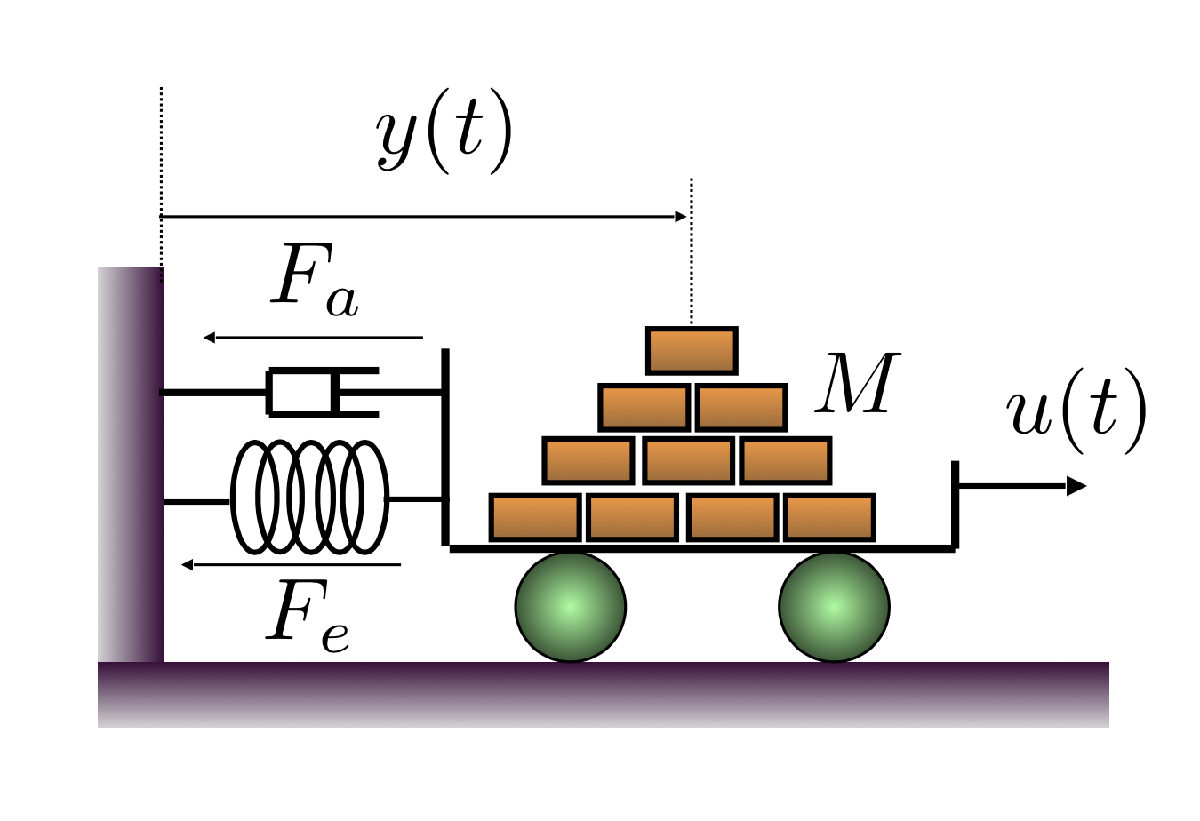

- control input: the external force $F$

- controlled output: the position of the cart $x$

- reference output: the desired position $w = x^{o}$

- elastic spring force: $F_e = k x$

- damper viscous friction force: $F_a = h \dot{x}$

A real system that can be described by the mechanical model we are analysing is, for example, the one depicted in the figure below:

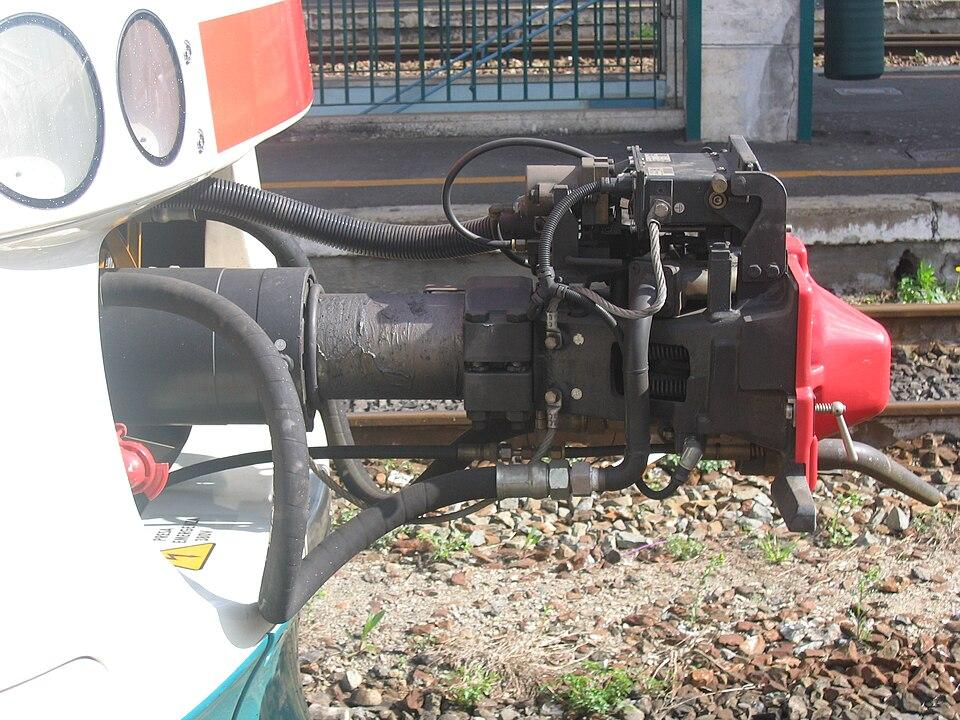

ALn501-502 "Minuetto" MD21, coupling system ([Source](https://commons.wikimedia.org/w/index.php?curid=718555)).

### Dynamic Modelling

The effects of mass, spring, and damper are not negligible, and dynamic behaviours such as oscillations may occur.  **Models capturing the dynamic modes of behaviour are clearly necessary**.


$$\text{sum of all external forces } \;=\; M \ddot{x} \quad \Longrightarrow \quad F - F_e -F_a = M \ddot{x} \quad \Longrightarrow \quad M \ddot{x} +h\,\dot{x} +k\,x = F$$


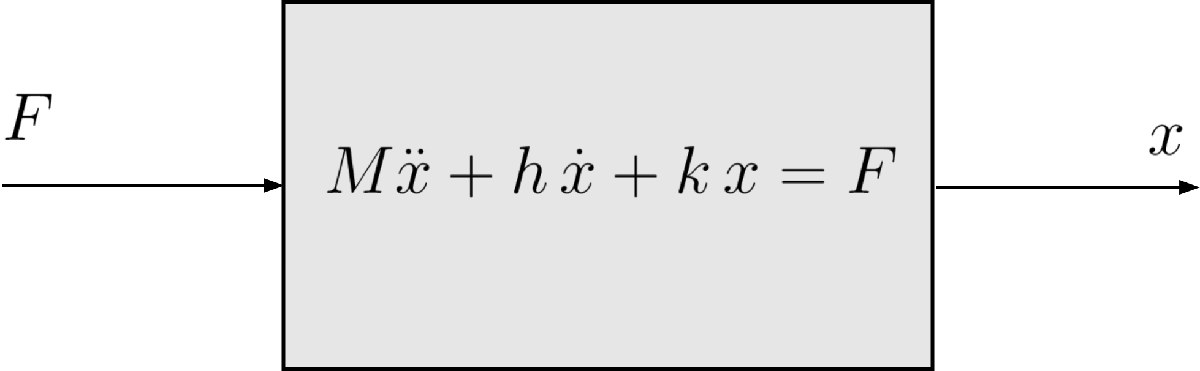

## Open-Loop Control Strategy: Performance Analysis

We would like to control the cart position $x$ by applying the simple open-loop control law


$$F = \bar{k} \,x^{o}$$


where $\bar k$ is the nominal value of the spring constant.

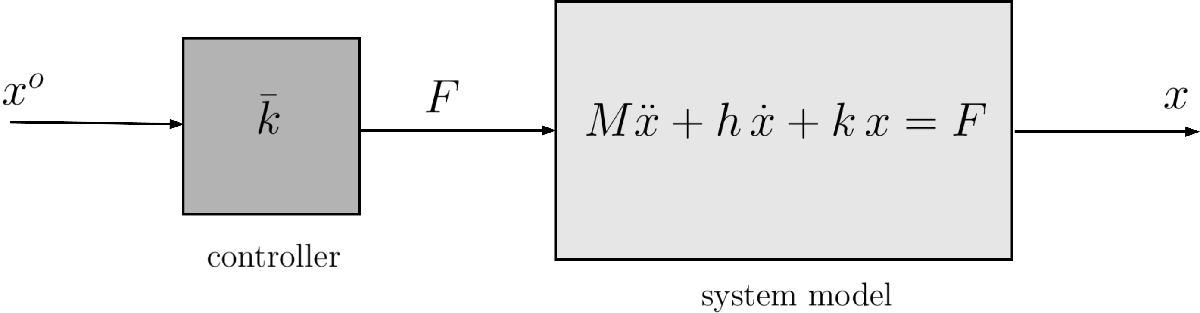

The system dynamics is now described by:


$$M \ddot{x} + h \dot{x} + k\, x = \bar k \, x^{o}$$


with initial conditions $x(0) = \bar x$ and $\dot{x}(0) = \bar v$.

- How does the system behave when the initial conditions change? 

- What happens if the spring's elastic constant $k$ takes on a value other than the nominal value $\bar k$?

- What if another parameter (the mass $M$, or the damping constant $h$) assumes a value different from the nominal one?

Let's analyse the performance of the proposed control strategy, implementing the model and simulating its behaviour in different scenarios.

### The Dynamic Model  & the Control Strategy in Matlab

The initial set of parameters' values is as follows:


$$\begin{array}{rclcrcl}
M&=& 123.52 \,\text{kg} & \quad & h&=& 9.12 \, \text{Ns/m} \\
\bar{k} &=& 10.09 \, \text{N/m} &\quad & k&=& 10.09 \, \text{N/m}
\end{array}$$


% -------------------------------------------------------------------
% The current script allows to simulate the FeedForward control of 
% the cart system, described in Part1 of the course material .
%
% To perform the simulation, the script uses the MATLAB command ode
% ------------------------------------------------------------------- 

clear % let's clean the Matlab workspace
close all
clc

### Performance Analysis

- How does the performance of the controlled system change when the initial conditions change?

- What if the spring elastic constant $k$ should assume a value different from the nominal one $\bar k$?

- Does the dynamic behaviour of the system depend also on the controller or only on the system's parameters $M,\,h,\,k\,$? 

- Using the open-loop control strategy are we able to impose a desired dynamic behaviour to the system?

To answer these questions, try changing the initial conditions, or the spring constant, or the system parameters (or all of these) and simulate the behaviour of the system.

#### Initial Conditions

Modify the initial position $x(0)$ and the initial speed $\dot{x}(0)$ of the cart and analyse the result

 

init_pos   = 0.75; % initial position [m]
init_speed = 0.5; % initial speed [m/s]

- Check the simulation result.

#### Nominal Value of the Spring Elastic Constant

This is the unique system information used to design the open-loop control strategy we are analysing. 

- What would happen if the actual spring constant in the system had a value other than the nominal value? 

- Would the performance of the control system remain the same? Would it improve? Would it get worse?

Put $k = \bar k$ ( $\bar k = 10.09\;\text{N/m} $ ) in the system's parameter set, simulate the behaviour and then select $k \ne \bar k$ (for instance $k=10.89$). Simulate one more time and compare the results.

 

k_bar = 10.09; % N/m 

- Check the simulation result.

#### Setting the System Parameters

 Verify that the nominal set of system's parameters corresponds to a damped oscillating behaviour:

 

M = 123.52;  % kg [cart mass]
h = 9.12;   % Ns/m [damping constant] % 9.12;
k = 10.09;   % N/m [spring elastic coeff.] <-- change the value; use for instance k = 10.89    
% using this set of params --> roots([M h k]) complex conj.
% 

- Check the simulation result.

In fact, given the differential equation 


$$M\, \ddot{x} + h \,\dot{x} + k \,x = \bar{k} \,x^{o}$$


the associated polynomial algebraic equation is 


$$M\, \lambda^2+h\,\lambda + k = 0$$


and its roots are

roots_CharPolyODE = roots([M h k])

roots_CharPolyODE =   -0.0369 + 0.2834i
  -0.0369 - 0.2834i


Change the damping constant, using for instance the value $\hat{h} = 90.12 \; \text{[Ns/m]}\,$and verify that the system behaviour is very different: no more damped oscillations, just a smooth decay to the asymptotic behaviour. 

Note: the roots of associated polynomial algebraic equation are distinc real values if you are using the value $\hat{h} = 90.12 \; \text{[Ns/m]}\,$. 

What if the actual spring constant $k$ is different from the nominal value $\bar k$?

Modify the spring constant value $k$ and analyse the result.

#### Assigning the Set-Point

Assign the desired carriage position. 

- Can the current control law guarantee that the desired position is reached?

 

x0 = 8.2;    % m [desired cart position -- setpoint]

- Check the simulation result.

#### Simulation Time Interval

Set the duration of the simulation:

 

tf = 270; % final time instant for the simulation
% The simulation makes it possible to determine the behaviour
% of the cart in the time interval [0, finalT].

- Check the simulation result.

### Solving an Ordinary Differential Equation in MATLAB

We would solve the second-order Ordinary Differential Equation (ODE)


$$M \ddot{x}(t) + h \dot{x}(t) + k\, x(t) = \bar k \, x^{o} \;, \qquad x(0) =\bar x\,,\quad \dot{x}(0) = \bar v$$


in MATLAB, numerically, using the command `ode`.  

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

Thus, given the second-order ODE to solve, we must perform a two-step procedure to obtain the (numerical) ODE solution using the MATLAB command `ode`:

**First** **Step**: Let's transform the second-order ODE in a system of two first-order ODEs. Using the substitutions


$$y_1(t) := x(t) \,,\qquad y_2(t) := \frac{d\,x(t)}{dt} = \dot{x}(t)$$


we obtain the following system of two first-order ODEs


$$\left\{\begin{array}{l}
M \ddot{x}(t) + h \dot{x}(t) + k\, x(t) = \bar k \, x^{o} \\
x(0) =\bar x\,,\quad \dot{x}(0) = \bar v \\ \\
y_1(t) := x(t)\\ 
y_2(t) := \frac{d\,x(t)}{dt} = \dot{x}(t)
\end{array} \quad \Longrightarrow \quad 
\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& y_2(t) \\
\dot{y}_2(t) &=&-\frac{k}{M}\,y_1(t) -\frac{h}{M}\,y_2(t) + \frac{\bar k}{M}\, x^{o} \\ \\
y_1(0) &= & \bar x \\
y_2(0) &=& \bar v
\end{array} \right. $$


**Second** **Step**: Define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`


$$\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& y_2(t) \\
\dot{y}_2(t) &=&-\frac{k}{M}\,y_1(t) -\frac{h}{M}\,y_2(t) + \frac{\bar k}{M}\, x^{o} \\ \\
y_1(0) &= & \bar x \\
y_2(0) &=& \bar v
\end{array} \right.  \qquad \Longrightarrow \qquad y_1(t) = ?$$


% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
F_ODE = ode;                                 % let's initialise an ODE object
F_ODE.Parameters   = [M, h, k, k_bar, x0];   % the parameters of the differential equation
F_ODE.InitialValue = [init_pos, init_speed]; % the initial conditions
F_ODE.InitialTime = 0;                      % the initial time instant of the solution, where 
                                            % the initial conditions are applied
F_ODE.ODEFcn = @CartODE;                % CartODE is the MATLAB function describing the ODE, 
                                        % we would like to solve. 
                                        % The code of cartODE is at the end
                                        % of this live script.

#### Simulation of the Controlled System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
t0 = 0; % the initial time instant
% tf already assigned
S  = solve(F_ODE, t0, tf); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

cart_x = S.Solution; % the result of the IPv
t_stamps = S.Time;   % time instants corresponding to the solution samples 

### The Simulation Results: the Behaviour of the Controlled System

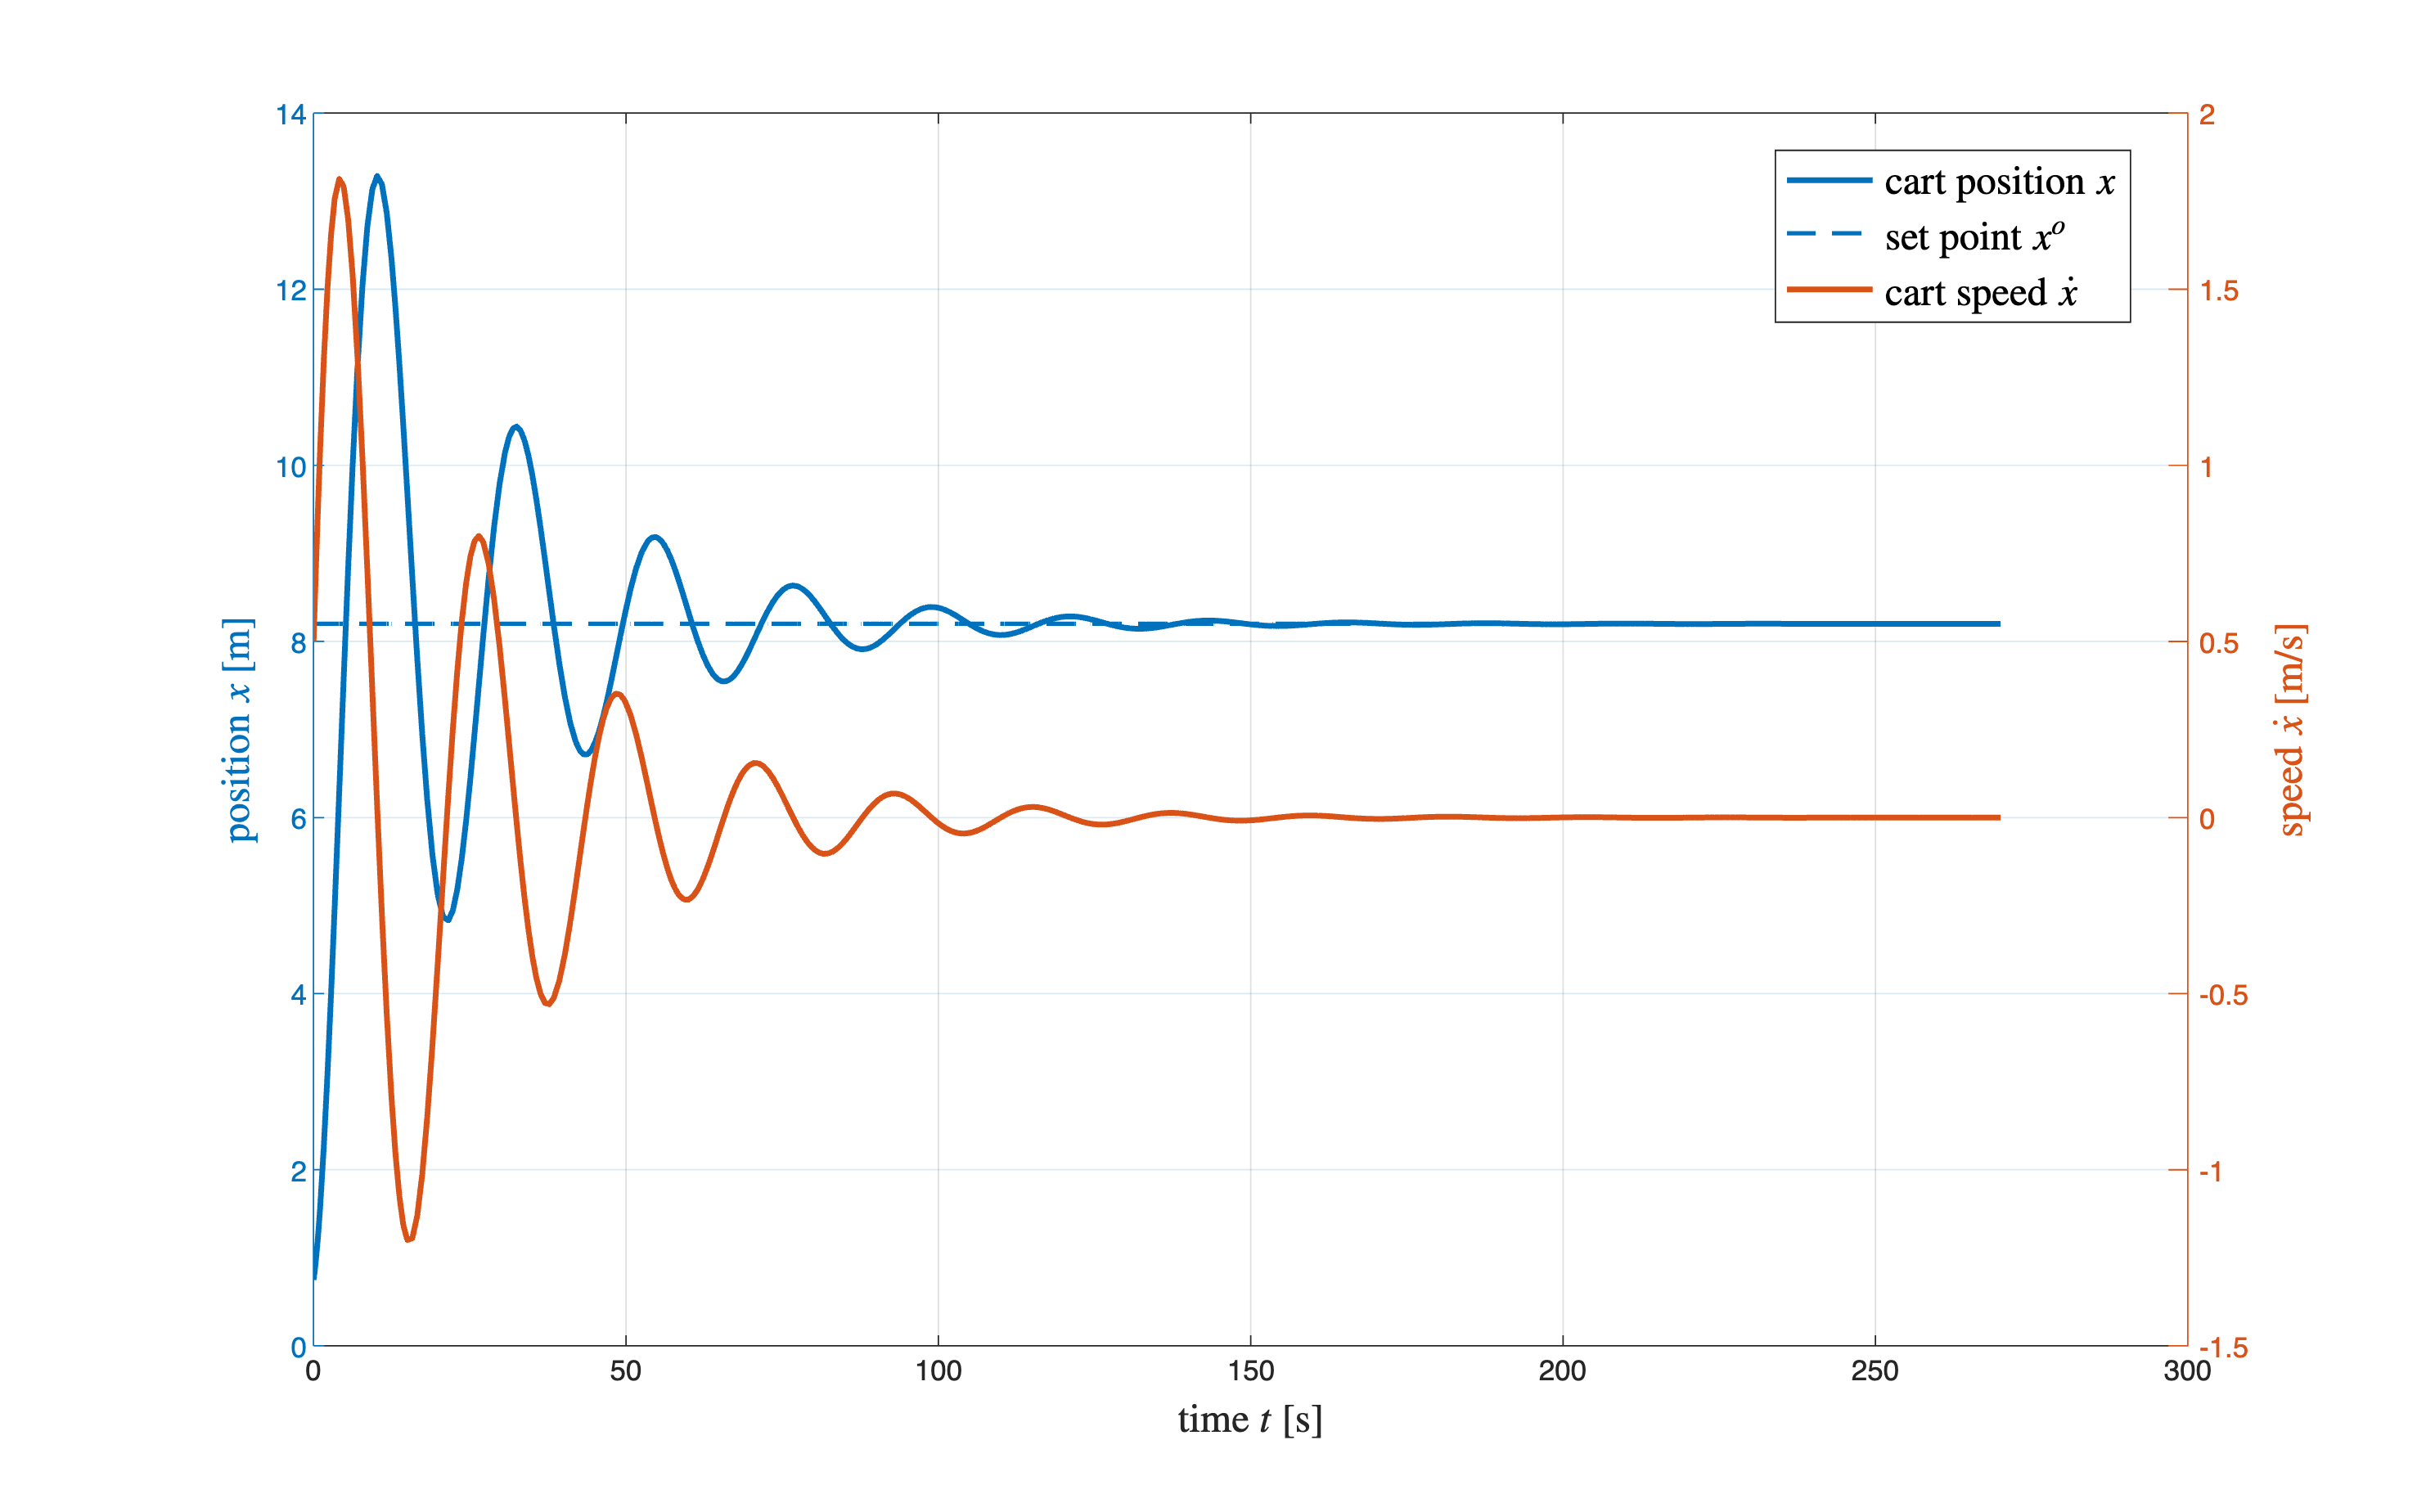

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.95]);
yyaxis left
plot(t_stamps, cart_x(1,:), 'LineWidth',2); % cart position vs time
hold on; % let's add another plot: the set-point
plot(t_stamps, x0*ones(size(t_stamps)),'LineStyle','--','LineWidth',1.5); 

xlabel('time $t$ [s]', 'FontSize', 14, 'Interpreter','latex'); % labels on the plot axes
ylabel('position $x$ [m]', 'FontSize', 14, 'Interpreter','latex'); 

yyaxis right
plot(t_stamps, cart_x(2,:), 'LineWidth',2); % cart speed vs time
ylabel('speed $\dot{x}$ [m/s]', 'FontSize', 14, 'Interpreter','latex'); 
grid on; % let's insert a grid in the figure

legend('cart position $x$', 'set point $x^{o}$', 'cart speed $\dot{x}$',...
        'Interpreter', 'latex', 'FontSize', 14, 'Location', 'best' );% adding a legend

- Modify the simulation duration.

- Assign the set point.

- Set new system parameters.

- Change the nominal value of the spring elastic constant.

- Modify the initial conditions.

## The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& y_2(t) \\
\dot{y}_2(t) &=&-\frac{k}{M}\,y_1(t) -\frac{h}{M}\,y_2(t) + \frac{\bar k}{M}\, x^{o} 
\end{array} \right.$$


The MATLAB function must provide the first derivative vector $\big[ \dot{y}_1(t),\;\dot{y}_2(t) \big]^{\top}$, given the values of the functions $y_1$ and $y_2$ at the current time instant $t$ and the parameters'values.

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
function dydt = CartODE(t, y, p)
    % retrieving the parameters
    M_val    = p(1);
    h_val    = p(2);
    k_val    = p(3);
    Kbar_val = p(4);
    x0_val   = p(5);

    kM = k_val/M_val;
    hM = h_val/M_val;
    U  = (Kbar_val/M_val)*x0_val;

    dydt = [y(2); ...
            -kM*y(1)-hM*y(2)+U];

end % function